## Define Q-table and Initialize Agent

**Previous script -  **[MDP_MATLB_Environment](matlab:open('./MDP_Matlab_Environment.mlx'))`. Please complete the mentioned script before starting this script.`

This script is to manualy create a Q learning agent. It has been added to module to help understand-

- What happens when we initialize an agent using MATLAB

For that we define a function to create a Q-tables for the Q-learning Agent. The Q-table has-

- number of rows = number of states

- number of columns = number of actions

Q table is a lookup table where we calculate the maximum expected future rewards for action at each state. This table guides an agent to select the best action at each state.

For information on how to define a function in MATLAB, click on - [`function [y1,...,yN] = myfun(x1,...,xM)`](https://www.mathworks.com/help/matlab/ref/function.html#d123e448119)

function qtable = Agent()

load env.mat

number_of_states = numel(MDP.States);
number_of_actions = numel(MDP.Actions);

Header= {'Left', 'Right'};

% Create an array of initial Q-values with the dimensions equal to our
% expected q-table
initialqvalues = ones([number_of_states,number_of_actions])*5';

% Create a table named qtable using the function array2table
qtable= array2table(initialqvalues,"VariableNames",Header);

end

% here we declare all the Q-values to be 5. This can be any value - even random integers. If all the values are
% equal then it means that the agent gives equal preference to all state-action pairs

The expected output of this function would look like this:-

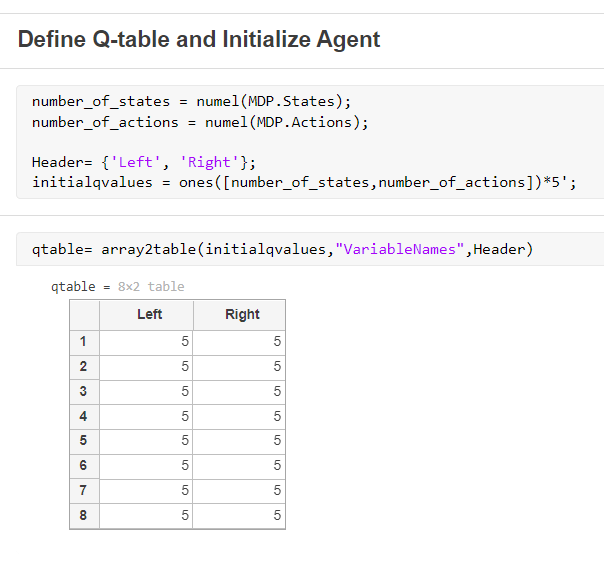

This is the second script of this lab. Please [click here](matlab:open('./Training_Explanation.mlx')) to move on to the next script `Training_Explanation``.mlx`